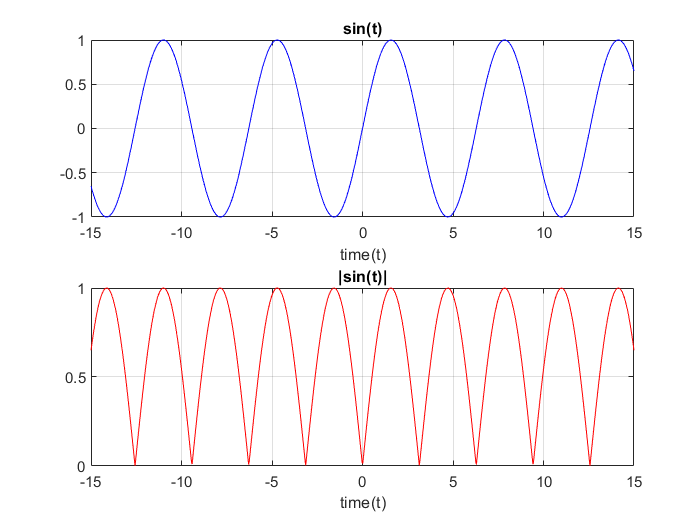

clear
clc
t=linspace(-15,15,1000);
x1=sin(t);
x2=abs(sin((1).*t));
cero=(zeros(length(t)));

figure
subplot(2,1,1)
plot(t,x1,'b')
hold on 
grid on
%plot(t,cero,'k')
title ('sin(t)')
xlabel('time(t)')

subplot(2,1,2)
plot(t,x2,'r')
grid on
title('|sin(t)|')
xlabel('time(t)')

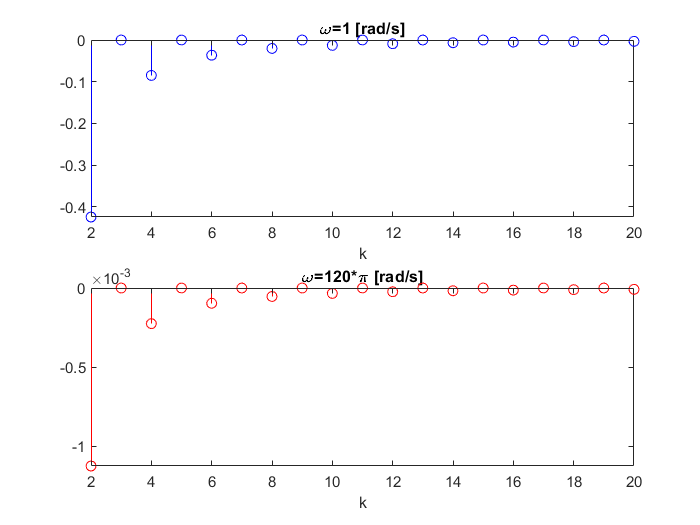




% omega0=1;
% f0=2*pi*omega0;
% T0=1/f0;
% dt=1/(100*f0);
% index=1;
% n=15;
% for k=-n:n;
% % Notice that this expression is also valid for k=0
%     c(index)=dt*sum(x2.*exp(-1i*k*2*pi*t/T0))/(10*T0);
% % Or equivalently: c(index)=mean(x.*exp(-1i*k*2*pi*t/T0));
%     index=index+1;
% end
% 
% k=-n:n;
% magnitude=abs(c);
% phase=angle(c);
% figure
% stem(k,magnitude)
% figure
% stem(k,phase)
% x_5=FourierSeries(x1,T0,15);
% plot(t,x_5)

k=2:20;
omega_1=1;
omega_120=120*pi;

T_1=pi/1;
T_120=1/240;
hj=omega_120*T_120;

a1=(-1/(pi)*((((cos((1+k).*(pi)))-1)./(1+k))+(((cos((1-k).*(pi)))-1)./(1-k))));

a120=(-1/(pi*omega_120))*((((cos((1+k).*(2*omega_120*T_120)))-1)./(1+k))+(((cos((1-k).*(2*omega_120*T_120)))-1)./(1-k)));

figure
subplot(2,1,1)
stem(k,a1,'b')

title ('\omega=1 [rad/s]')
xlabel('k')

subplot(2,1,2)
stem(k,a120,'r')
title('\omega=120*\pi [rad/s]')
xlabel('k')

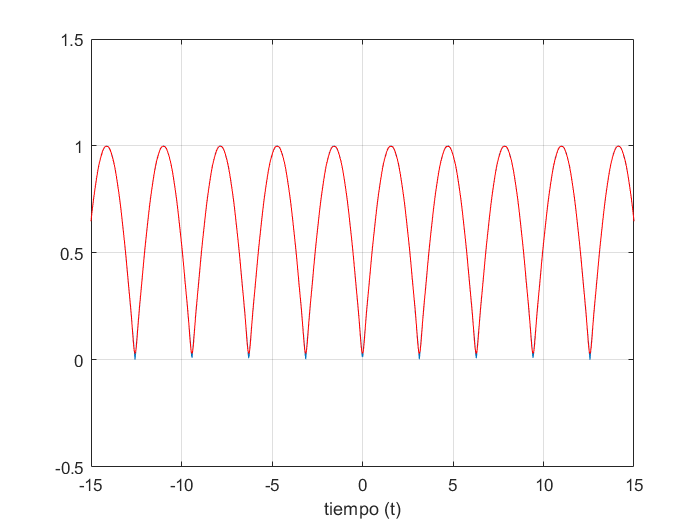

a0 = 2/pi;
xe = a0*ones(1,length(t));
for i = 1:length(k)
    xe = xe + a1(i).*cos((i+1)*omega_1*t); %+ bk(i)*sin(i*omega0*t);
    clf
    plot(t,x2)
    ylim([-0.5,1.5])
    hold on
    grid on
    plot(t,xe,'r')
    xlabel('tiempo (t)')
    pause(0.5)
end

% t=-20:0.01:20;
% n=100;
% omega_1=1;
% omega_120=120*pi;
% 
% T_1=pi/1;
% T_120=1/240;
% 
% for i=1:length(t)
%     y(i)=2/pi;
%     for k=2:1:n
%         y(i)=y(i)+ (-1/(pi)*((((cos((1+k).*(omega_1*T_1)))-1)./(1+k))+(((cos((1-k).*(omega_1*T_1)))-1)./(1-k)))).*cos(k*t(i));
%      end
% end

% function [f] =FourierSeries (x,T,n)
%     dt=T/100;
%     t=linspace(-15,15,1000);
%     omega0=(2*pi)/T;
%     index=1;     
%     for k=-n:n
%         c(index)=dt*sum(x.*exp(-1i*k*2*pi*t/T))/(T);        
%         index=index+1;
%     end    
%     ak=real(c);
%     bk=imag(c);
%     index_2=1;  
%     ce=zeros(1,length(t));    
%     for k=-n:n
%         ce=ce+c(index_2)*exp(1i*k*omega0*t);
%         %ce=ce + ak(index_2)*cos(k*omega0*t) +bk(index_2)*sin(k*omega0*t);
%         index_2=index_2+1;
%     end
%     f=(ce);
% end